data = importdata("Assignment_Data_SC42145_2022.mat")

data = struct with fields:
           A: [5×5 double]
           B: [5×3 double]
           C: [2×5 double]
           D: [2×3 double]
         FWT: [2×3 ss]
    WindData: [60001×2 double]


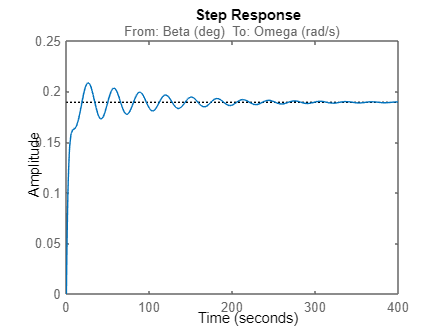


FWT = data.FWT;
A=data.A;
B=data.B;
C=data.C;
D=data.D;
%print(data)
sys1 = ss(A,B,C,D);


step(-FWT(1,1));

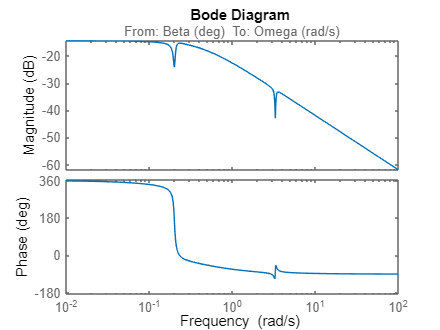

bode(-FWT(1,1));

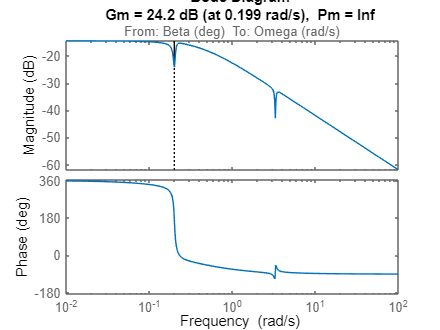

margin(-FWT(1,1)); 

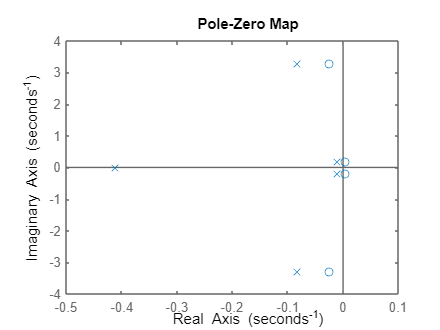

pzplot(-FWT(1,1));

stepinfo(-FWT(1,1));


% PID controller
Plant = -FWT(1,1);
Kp = 40000;
Ki = 50.2;
Kd = 400;
Tf = 0.06;
C = pid(Kp,Ki,Kd,Tf)

C =
 
             1            s    
  Kp + Ki * --- + Kd * --------
             s          Tf*s+1 

  with Kp = 4e+04, Ki = 50.2, Kd = 400, Tf = 0.06
 
Continuous-time PIDF controller in parallel form.



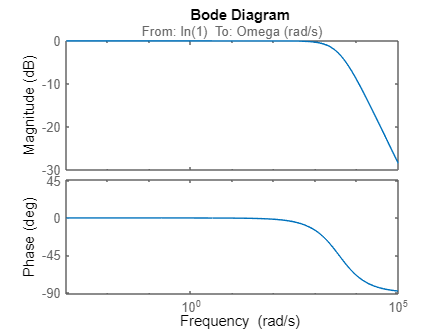


fbsys = feedback(Plant*C,1);
bode(fbsys)

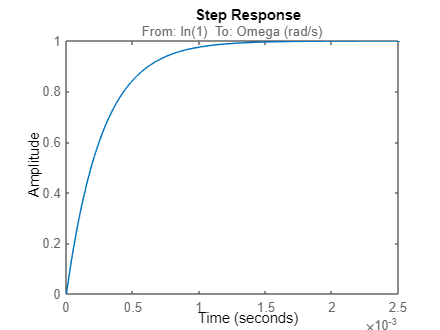

step(fbsys)

stepinfo(fbsys)

ans = struct with fields:
         RiseTime: 5.9083e-04
    TransientTime: 0.0011
     SettlingTime: 0.0011
      SettlingMin: 0.9038
      SettlingMax: 0.9992
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9992
         PeakTime: 0.0028
